% --------- Double Pantograph (6-DOF) (ref. Stocco's thesis) ---------------

% This script calculates the direct kinematics problem of the 6DOF robot
% Inputs: 
%         Motor angles [q1 q2 q3 q4 q5 q6 q7] rad
%         Linkage lengths [l1 l2 l3 l4 l5 l6 l7 l8] cm -> currently internal

% Outputs: 4x4 Transformation from base to end-effector frame (XYZ, pose)
%          4x4 Transformations from base to all intermediate frames

% Figure 7.2 shows linkage lengths, active (motor) joints q

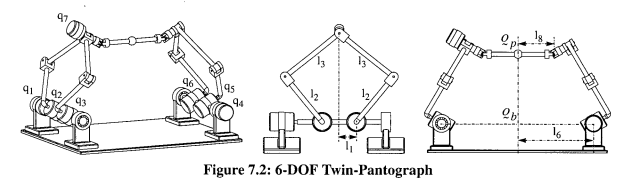

% Figure A.12 shows full 'serialized' version of 7.2 on left, half on right
% This INCLUDES pseudo-active joints in the serial chain - solved first
% Note that left is composed of the right side + segments thetas1-3 repeated

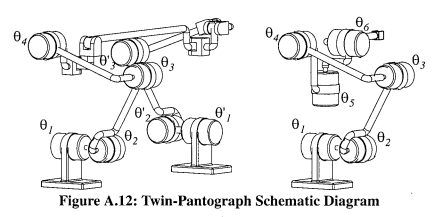

% Figure A.2 is the unfolded (all actuator angles = 0deg) schematic of the
% right 'serialized' kinematic chain on the right side of A.12

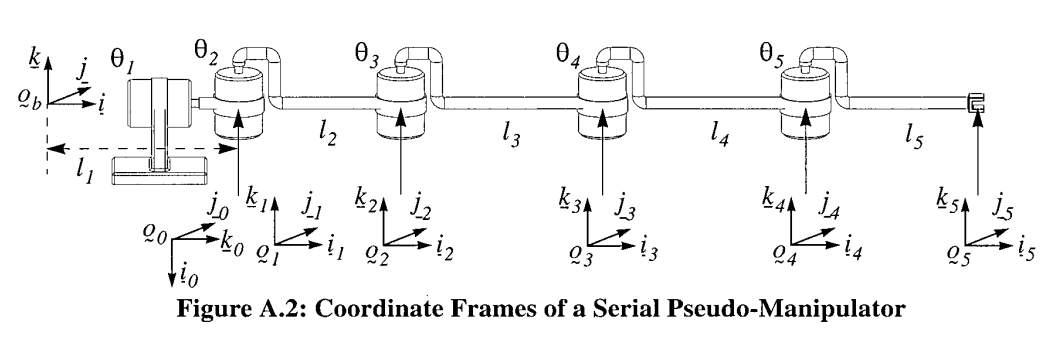

% First we compute the chain above -- the right pantograph from base to e-e:

shoulderAngle_A = 0; % INPUT pitch of the TOP shoulder
pantoAngleR_A = 47.45 * (2*pi)/360; % INPUT rotation of right pantograph motor
pantoAngleL_A = pi -  50.94 * (2*pi)/360; % INPUT of left motor

[Tb_0, Tb_1, Tb_2, Tb_3] = fiveBarForward(shoulderAngle_A, pantoAngleL_A, pantoAngleR_A)

q4_2y = -0.6694

gamma3 = 0.8539

gamma3deg = 48.9489

gamma4 = 0.7056

gamma4deg = 40.4457

theta3 = 1.5822

theta3deg = 90.6966

Tb_0 =     1.0000         0         0  -20.0000
         0    0.0000   -1.0000    2.0200
         0    1.0000    0.0000         0
         0         0         0    1.0000


T0_1 =     0.0000         0   -1.0000         0
         0    1.0000         0         0
    1.0000         0    0.0000         0
         0         0         0    1.0000


T1_2 =     0.6762   -0.7367         0   11.3742
    0.7367    0.6762         0   12.3911
         0         0    1.0000         0
         0         0         0    1.0000


T2_3 =    -0.0114   -0.9999         0   -0.1942
    0.9999   -0.0114         0   17.0989
         0         0    1.0000         0
         0         0         0    1.0000


Tb_3 =    -0.0000   -0.0000   -1.0000  -20.0000
    0.7443    0.6678   -0.0000    3.3736
    0.6678   -0.7443    0.0000   23.8109
         0         0         0    1.0000


frame0XYZ =   -20.0000    2.0200         0


frame1XYZ =   -20.0000    2.0200         0


frame2XYZ =   -20.0000   -9.3542   12.3911


endEffectorXYZ =   -20.0000    3.3736   23.8109


Tb_0 =     1.0000         0         0  -20.0000
         0    0.0000   -1.0000    2.0200
         0    1.0000    0.0000         0
         0         0         0    1.0000


Tb_1 =     0.0000         0   -1.0000  -20.0000
   -1.0000    0.0000   -0.0000    2.0200
    0.0000    1.0000    0.0000         0
         0         0         0    1.0000


Tb_2 =     0.0000   -0.0000   -1.0000  -20.0000
   -0.6762    0.7367   -0.0000   -9.3542
    0.7367    0.6762    0.0000   12.3911
         0         0         0    1.0000


Tb_3 =    -0.0000   -0.0000   -1.0000  -20.0000
    0.7443    0.6678   -0.0000    3.3736
    0.6678   -0.7443    0.0000   23.8109
         0         0         0    1.0000



% The right pantograph e-e has a coincident origin with subsequent frames 4,5
% Recall this is the side with a spherical joint (4,5,6) and only q4 motor

% Transformation from frame 3 -> 4 (only rotation)
eul = [theta4 0 -pi/2]; % Identity (no rotation) matrix
a = eul2rotm(eul); 
c = [0;0;0]; % load the translation column vector

b = zeros(4,4); % initialize empty hom. 4x4 matrix
b(1:3,1:3) = a; % insertion of rot 3x3 into hom. 4x4
b(1:3, 4) = c; % insertion of translation vector into 4x4
b(4,4) = 1; % insertion of view factor into 4x4
b; % completed homogeneous 4x4 matrix

b =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000



T3_4 = b

T3_4 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000



% Transformation from frame 4 -> 5 (only rotation)
eul = [theta5 pi/2 0]; % Identity (no rotation) matrix
a = eul2rotm(eul); 
c = [0;0;0]; % load the translation column vector

b = zeros(4,4); % initialize empty hom. 4x4 matrix
b(1:3,1:3) = a; % insertion of rot 3x3 into hom. 4x4
b(1:3, 4) = c; % insertion of translation vector into 4x4
b(4,4) = 1; % insertion of view factor into 4x4
b; % completed homogeneous 4x4 matrix

b =     0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000



T4_5 = b

T4_5 =     0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000


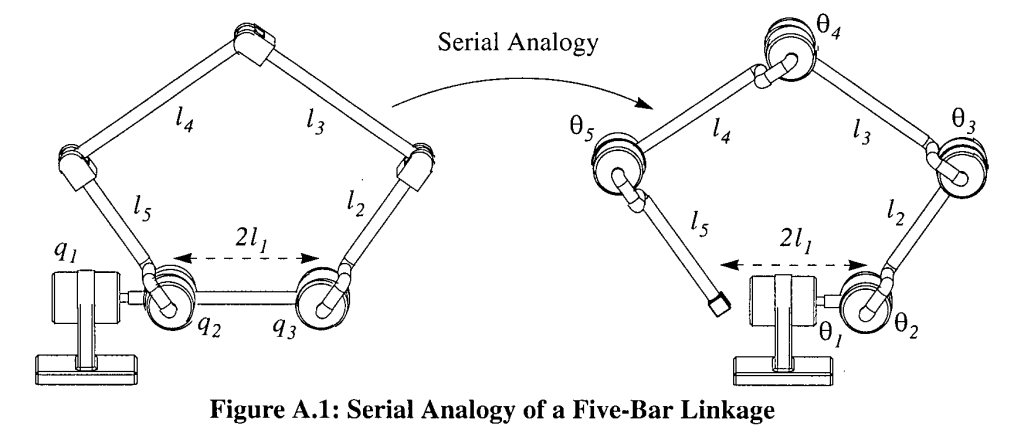

%{

 --------- Five-bar with shoulder (ref. Stocco's thesis) ---------------

 This function returns the 4x4 Transformation matrices for the final and
 intermediate frames of the 5-bar + shoulder pantograph linkage, from an
 origin base coordinate frame {0 0 0}.

 INPUTS: shoulder encoder angle (rad), left pantograph encoder angle, right
 pantograph encoder angle
    
 OUTPUTS: Four 4x4 Transformation matrices for base>frame_n (n = 0,1,2,3)
          Where 3 is the end effector
%}

% NOTE: for utility of this model we only need to translate base frame to
% the end effector @ theta4, we don't care about the left side motor/elbow

function [Tb_0, Tb_1, Tb_2, Tb_3] = fiveBarForward(shoulderAngle, pantoAngleL, pantoAngleR)

% Active (Encoded Motor) joint angles in rad*
theta1 = shoulderAngle; % INPUT pitch of the shoulder
theta2 = pantoAngleR; % INPUT rotation of right pantograph motor
q2 = pantoAngleL;


% Pseudo-Active joint angles in rad*
theta3 = 0;
theta4 = 0;
theta5 = 0;

% Bar lengths in cm*
l1 = 4.04/2; % Half of distance between panto motors

l2 = 16.820; % Motor to elbow linkage length
l5 = 16.820;

l3 = 17.10; % Elbow to tip linkage length
l4 = 17.09;

l6 = 20; % Half of distance between shoulder motors

% all linkage lengths in the x-dir of respective parent frames...
l1vec = [l1;0;0]; % Half of distance between panto motors

l2vec = [l2;0;0]; % Motor to elbow linkage length
l5vec = [l5;0;0];

l3vec = [l3;0;0]; % Elbow to tip linkage length
l4vec = [l4;0;0];

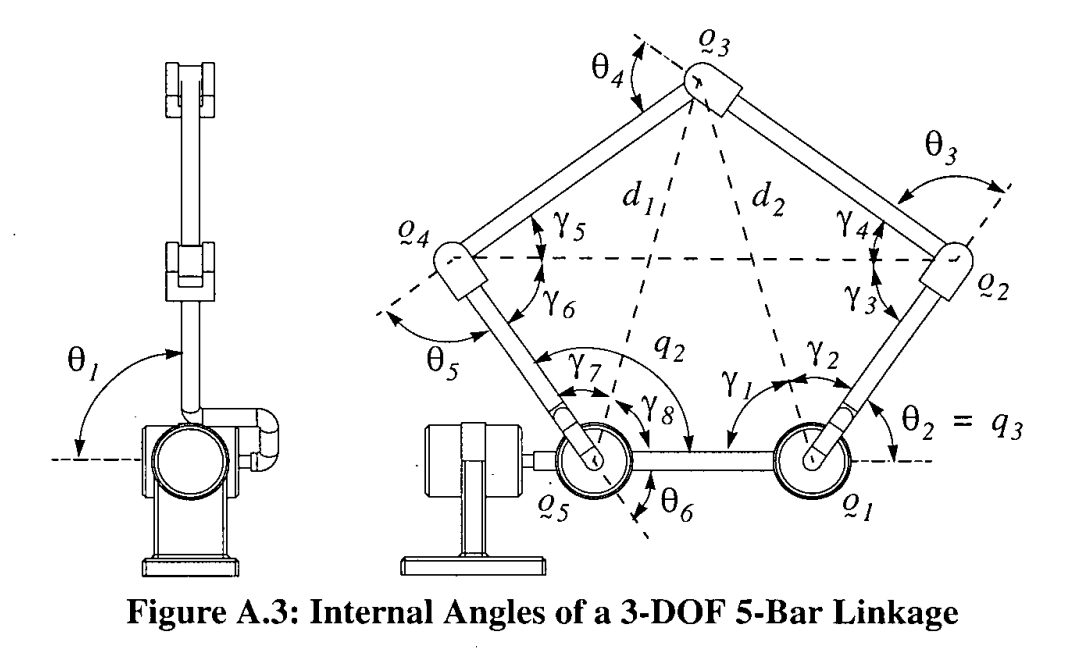

% 2D Inverse Kinematics to solve pseudo joint angle theta3 - [x0, y0 at Q1]
% Again, we do not care about anything past this, our end effector is Q3

q1_2x = l2*cos(theta2);
q1_2y = l2*sin(theta2);
q1_2 = [q1_2x; q1_2y];

% q4_2 is the vector drawn from q2 > q4 drawn above
q4_2x = q1_2x + 2*l1-l5*cos(q2);
q4_2y = q1_2y - l5*sin(q2)
q4_2 = [q4_2x; q4_2y];

% Leo's math here gets quarantined:
% gamma3 = 2*atan2(norm(q4_2 - q1_2), norm(q4_2 + q1_2)) * sign(theta2 - atan2(q4_2y,q4_2x))

% Compute the angle of vector q4_2
angle_q4_2 = atan2(q4_2y, q4_2x);

% Calculate gamma3 as the difference between theta2 and angle_q4_2 relative
% to base x-axis
gamma3 = theta2 - angle_q4_2
gamma3deg = gamma3 * 360 /6.28

gamma4 = pi - 2*atan(sqrt(((norm(q4_2) + l3)^2 - l4^2) / (l4^2 - (norm(q4_2) - l3)^2)))
gamma4deg = gamma4 * 360 /6.28

theta3 = pi - gamma3 - gamma4 % was playing with the error + (5* 2*pi/360)
theta3deg = theta3 * 360 /6.28



% test fix case: theta3 = 90.64 * 2 * pi / 360 % error of -4.2154deg



% Matrix Transformations

eul = [0 0 pi/2]; % Z-Y-X, or k-j-i !!!
Cb_0 = eul2rotm(eul);
c = [-l6; l1; 0]; % x offset is half panto motor distance, z offset is half shoulder dist
Tb_0 = zeros(4,4); % initialize empty hom. 4x4 matrix
Tb_0(1:3,1:3) = Cb_0; % insertion of rot 3x3 into hom. 4x4
Tb_0(1:3, 4) = c; % insertion of translation vector into 4x4
Tb_0(4,4) = 1; % insertion of view factor into 4x4
Tb_0 % completed homogeneous 4x4 matrix

eul = [theta1 -pi/2 0]; 
C0_1 = eul2rotm(eul);
c = [0; 0; 0]; 
T0_1 = zeros(4,4); % initialize empty hom. 4x4 matrix
T0_1(1:3,1:3) = C0_1; % insertion of rot 3x3 into hom. 4x4
T0_1(1:3, 4) = c; % insertion of translation vector into 4x4
T0_1(4,4) = 1; % insertion of view factor into 4x4
T0_1 % completed homogeneous 4x4 matrix

eul = [theta2 0 0]; 
C1_2 = eul2rotm(eul); 
c = C1_2*l2vec; 
T1_2 = zeros(4,4); % initialize empty hom. 4x4 matrix
T1_2(1:3,1:3) = C1_2; % insertion of rot 3x3 into hom. 4x4
T1_2(1:3, 4) = c; % insertion of translation vector into 4x4
T1_2(4,4) = 1; % insertion of view factor into 4x4
T1_2 % completed homogeneous 4x4 matrix

eul = [theta3 0 0]; 
C2_3 = eul2rotm(eul); 
c = C2_3*l3vec; 
T2_3 = zeros(4,4); % initialize empty hom. 4x4 matrix
T2_3(1:3,1:3) = C2_3; % insertion of rot 3x3 into hom. 4x4
T2_3(1:3, 4) = c; % insertion of translation vector into 4x4
T2_3(4,4) = 1; % insertion of view factor into 4x4
T2_3 % completed homogeneous 4x4 matrix

% Overall Transformation:
Tb_3 = Tb_0 * T0_1 * T1_2 * T2_3


% Debug parameters:
frame0XYZ = Tb_0(1:3, 4).'

Tb_1 = Tb_0 * T0_1;
frame1XYZ = Tb_1(1:3, 4).'

Tb_2 = Tb_0 * T0_1 * T1_2;
frame2XYZ = Tb_2(1:3, 4).'

%End effector coordinates [x y z]
endEffectorXYZ = Tb_3(1:3, 4).'

end